# **The Challenge of Future Energy Systems: Analysis of the Voltage Drop in Transmission Lines**

## Date: April 26th, 2017

## Authors: *Gonzalo Sánchez Contreras, Emilio de las Heras Páez de la Cadena, Ignacio Sanz Soriano*

**Objective: **The aim of this notebook is to analyze and compare transmission line simulation results with the real measures obtained in the laboratory in different load scenarios to study the effects on voltage, current and losses. To achieve these goal, we use a scale transmission line to take measures that are then rescaled to real ones (132 kV, 100 MVA) and compare with simulation results using distributed parameters model.

# Technology (old and new) & Main Characteristics Low Voltage, Medium Voltage, High Voltage   

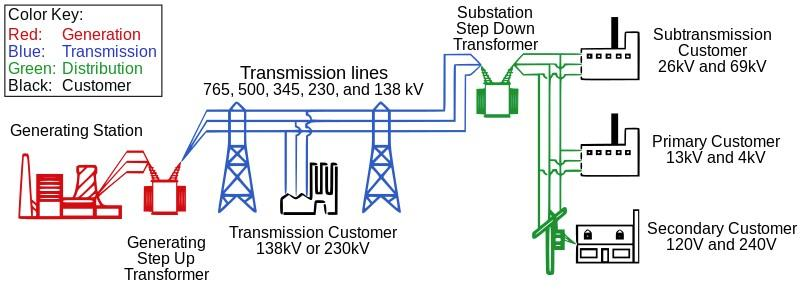

## **Transmission Lines (High-Medium Voltage)**

Transmission lines are those responsible for bulk movement of electrical energy (from generating substation to some consumption but mainly a distribution substation). Mostly AC systems, mix between Meshed and Radial.

- HV(defined differently for different regions) is used to have lower losses (due to lower currents).

- Transmission lines are predominantly overhead lines (exceptions are underground lines used for urban areas or environmentally sensitive locations). 

- Transmission is mainly 3-Phase AC although 1-Phase AC is sometimes used.

- HVDC is sometimes implemented for greater efficiency over very long distances (hundreds of kms), also submarine power cables and lastly, in the interchange of power between grids that are not mutually synchronized.

## Historically...

- In very early days, no transmission (DC & generation and loads located near each other).  19th 20th centuries saw a rapid industrialization of this power transmission system.

## What the future holds...

- High-temperature superconductors (HTS) promise to revolutionize power distribution by providing lossless transmission of electrical power. This would translate in having a “supergrid”. This is a system based on an idea for combining very long electric power transmission with liquid nitrogen distribution, to achieve superconductivity in the power lines.

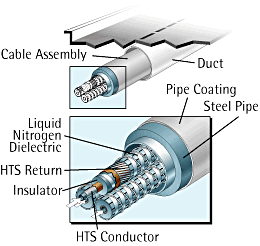

- HVDC as costs of inverters drop & interconnection between large power systems from different regions (no frecuency differences) (other advantages include no reactive power).

- Wireless power transmission has been studied for transmission of power from Solar power systems to the earth. A high power array of microwave or laser transmitters would beam power to a receiver. This option presents a major challenge for engineering and presents a high level of uncertainty.

## Distribution Lines (Low Voltage)

Distribution lines are those involved in the final stage of electrical power delivery (from distribution substation to low voltage consumption) 

- Almost always AC (excluding railway systems, telephone systems…). 

- Meshed.

- Since 1880s (when electricity began being generated at power stations) and currently (in most places) it is a one directional power flow due to centralized generation. 

## What the future holds...

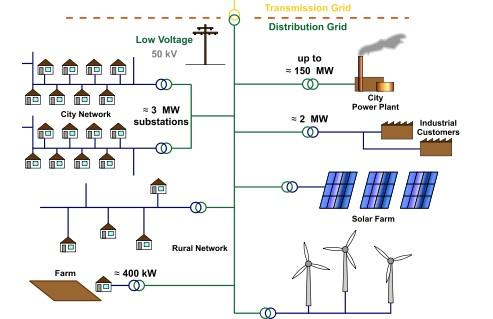

- Distributed generation presents a need for a two-directional distribution system: New regulation, smartgrids, storage (batteries, EVs), Voltage regulation capable of dealing with under and over voltage.  

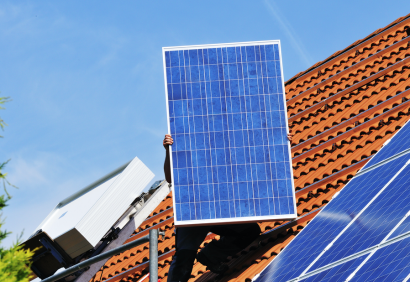

- DC (IF costs severely drop)

# Simulation: Voltage increase & checking different values of impedance in the lines

## Scaled Transmission Line (Laboratory)

**Electric parameters**

Frequency = 50 Hz

Voltage = 220 V

Current = 5 A


$$R = 1\: \Omega,\quad L = 11\:mH, \quad C = 2\cdot10^{-6}\: F$$


## Measures taken in the lab, feeding a variable load (cos$\varphi =1$)

clear all
% LECTURAS
V_inicial = [ 222 221 221 221 222 222 ];% V
V_final   = [224 216 208 199 190 182 ]; % V
Pot       = [ 0 1 2 3 4 5 ]*1000;       % W

Now, the $R_{\mathrm{load}\text{ }}$for each power consumption point measure is calculated.


$$R_{load}^{(i)} = \frac{(U_{load}^{(i)})^2}{P_{load}^{(i)}}\:(\Omega)$$


% Resistencia de carga 
R_load = [];
for i = 1:length(V_final)
    R_load(i) = V_final(i)^2/Pot(i);  
end
R_load

R_load =        Inf   46.6560   21.6320   13.2003    9.0250    6.6248


## Base Magnitudes of the Line to calculate *per unit* measures

frecuencia = 50;
omega = 2*pi*frecuencia;

% Magnitudes base de la línea
U = 220;
I = 5;
S = sqrt(3)*U*I;
Z = U^2/S;

% Parámetros eléctricos de la línea
R = 1;
L = 11e-3;
C = 2e-6;

% Parámetros en p.u.
r = R/Z;
x = omega*L/Z;
b = omega*C*Z;
r_load = R_load/Z;

% Medidas en p.u.
v_inicial = V_inicial/U;
v_final = V_final/U;

## Voltage Drop $(\Delta V)$ vs. Power Consumption $(P_{load})$

deltaV = v_inicial-v_final

deltaV =    -0.0091    0.0227    0.0591    0.1000    0.1455    0.1818


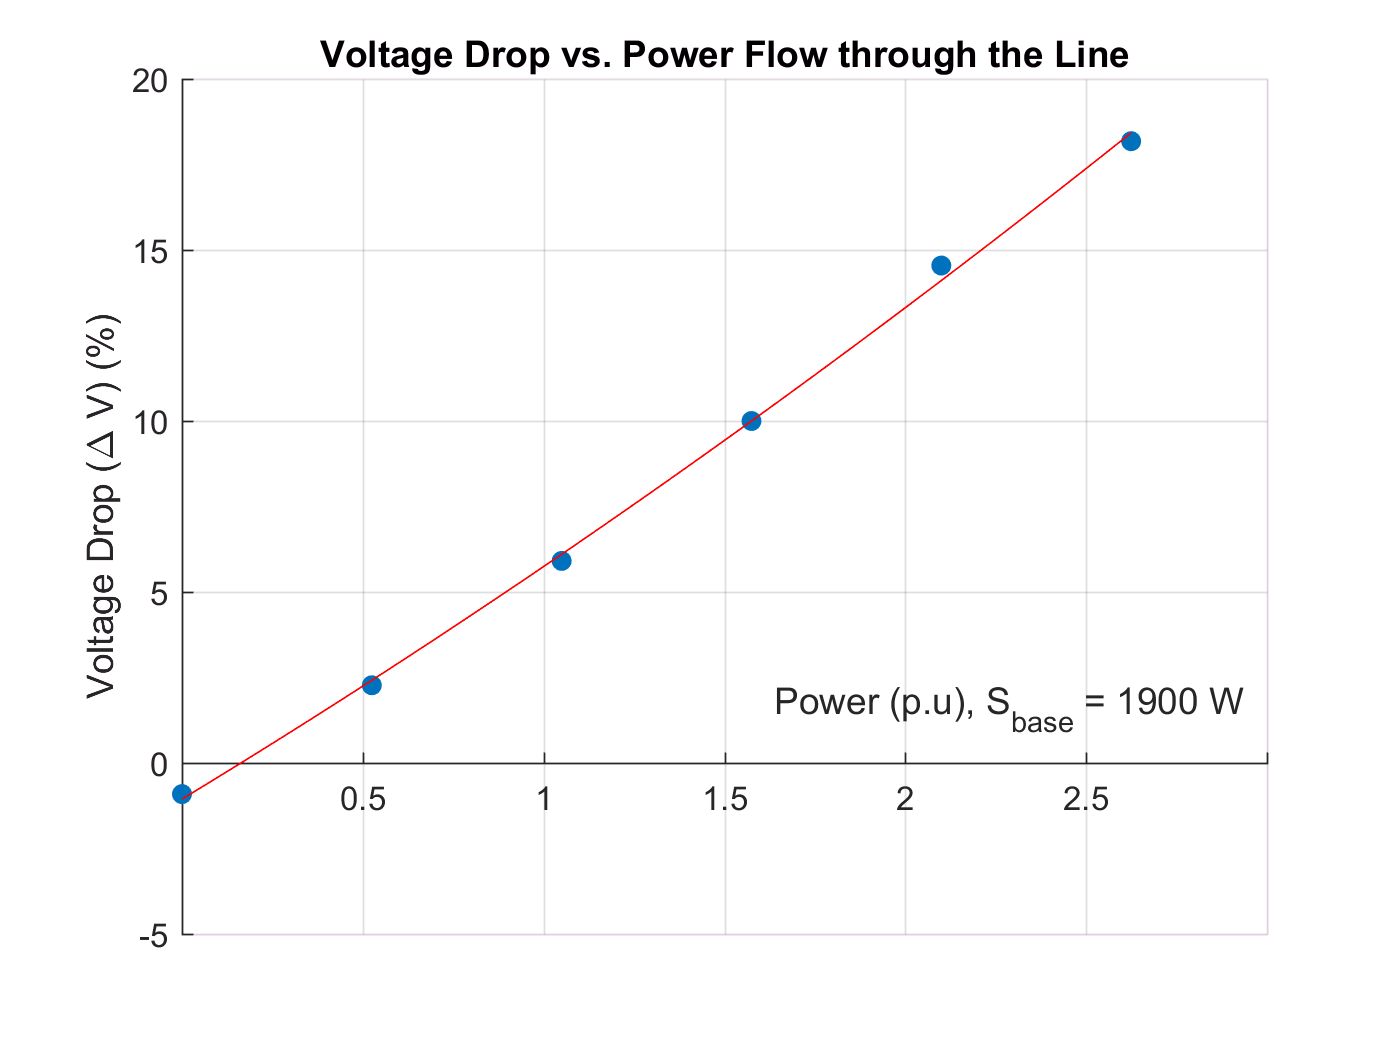

pot = Pot/S;

% Ajuste de puntos
p = polyfit(pot,deltaV,2);
x1 = linspace(0,max(pot));
y1 = polyval(p,x1);

ax = gca;
scatter(pot,deltaV*1e2,'fill');
hold on
plot(x1,y1*1e2,'r');
ax.XAxisLocation = 'Origin';
xlabel('Power (p.u), S_{base} = 1900 W ');
ylabel('Voltage Drop (\Delta V) (%)');
grid on
title('Voltage Drop vs. Power Flow through the Line');

## Modelling 132 kV, 100 MVA, 60 km Transmission Line

Now, once we have per unit parameters from the line in the lab, we re-scale them to the real 132 kV, 100 MVA, 60 km length transmission line obtaining the next electric parameters.

% PARÁMETROS
Ubase = 132e3/sqrt(3);
Sbase = 100e6/3;
Ibase  = Sbase/Ubase;
Zbase = Ubase^2/Sbase;

L = 60; % km
R = r*Zbase;
X = x*Zbase;

b = 0.0160

B = b/Zbase;

B = 9.1606e-05


Z = (R + j*X);
Y = j*B;
R_load = r_load*Zbase;
Pot = pot*Sbase;

V_inicial = v_inicial*Ubase;
V_final = v_final*Ubase;
I_load = V_final./R_load;
deltaV_lab = V_inicial - V_final;

The electric parameters of the 132 kV transmission line are:


$$R = 6.86\:\Omega\quad\chi=23.70\:\Omega\quad B = 3.05\cdot10^{-5}\:\Omega^{-1}$$


% Impedancia serie y admitancia paralelo
Zs = Z/L % Ohm/km

Zs = 0.9044

Yp = Y/L % S/km

Yp = 3.0535e-06

Referring them to the length of the line, we obtain:


$$R = 0.114\:\frac{\Omega}{km}\quad\chi=0.3950\:\frac{\Omega}{km}\quad B = 1.53\cdot10^{-6}\:\frac{1}{\Omega\cdot km}$$


Then, the propagation constant $\gamma = \sqrt{Z_s\cdot Y_p}$ and the characteristic impedance $Z_c= \sqrt{\frac{Z_s}{Y_p}}$ are calculated as follows:

% Constante de Propagacion
gamma = sqrt(Zs*(Yp));
gamma_A = sqrt(Zs*(Yp*1e6))% mrad/km

gamma_A = 1.6618

lambda = 2*pi*1e3/imag(gamma_A) % km

lambda = Inf

v = lambda*frecuencia/3e8 % m/s

v = Inf

% Impedancia caracteristica
Zc = sqrt(Zs/Yp)

Zc = 544.2274

abs(Zc)

ans = 544.2274

## Characteristic Power of the line

It is possible to calculate the characteristic power of the line as follows:


$$P_c = \frac{U_c^2}{|\bar{Z}_c|}$$


Pc = Ubase^2./abs(Zc)*1e-6

Pc = 11.1907

## Distributed Parameters Model

The calculation of Voltage and Current at the end of the line is made using the transfer matrix of distributed parameters for long transmission lines (line length bigger than 10 km).


$$\left\lbrack \begin{array}{c}
V_l \\
I_l 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
A & B\\
C & D
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
V_o \\
I_o 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{cosh}\left(\gamma \text{ }L\right) & -Z_c \mathrm{sinh}\left(\gamma \text{ }L\right)\\
-\frac{\mathrm{sinh}\left(\gamma \text{ }L\text{ }\right)}{Z_c } & \mathrm{cosh}\left(\gamma \text{ }L\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
V_o \\
I_o 
\end{array}\right\rbrack$$


% Modelo Real de parametros distribuidos
% Elementos de la matriz de transferencia (A,B,C,D)
A = cosh(gamma*L);
B = -Zc*sinh(gamma*L);
C = -sinh(gamma*L)/Zc;
D = cosh(gamma*L);
M = [A B;
    C D]

M =    0.9989 + 0.0003i  -6.8540 -23.6949i
   0.0000 - 0.0001i   0.9989 + 0.0003i


## Voltage drop simulation: Voltage at the begginig$\text{ }V_o$

**First hypothesis.** The input data for voltage drop simulation are the current feeding the load $I_{load}$ and the voltage in the load $V_{load}$. Then, changing the load (current at the end of the line), we obtain the different values of voltage drop depending on the power flow through the line.


$$\left\lbrack \begin{array}{c}
V_o \\
I_o 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{c}
A & B\\
C & D
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
V_l \\
I_l 
\end{array}\right\rbrack$$


Io = [];
Vo = [];
for i = 1:length(V_inicial)
    V0 = inv(M)*[V_final(i); I_load(i)];
    Io(i) = V0(2);
    Vo(i) = V0(1);
end

abs(Vo)*sqrt(3)

ans =    1.0e+05 *

    1.3425    1.3259    1.3195    1.3207    1.3383    1.3788


abs(Io);

After that, we plot the Voltage at the beginnig of the line versus the power flow through the line.

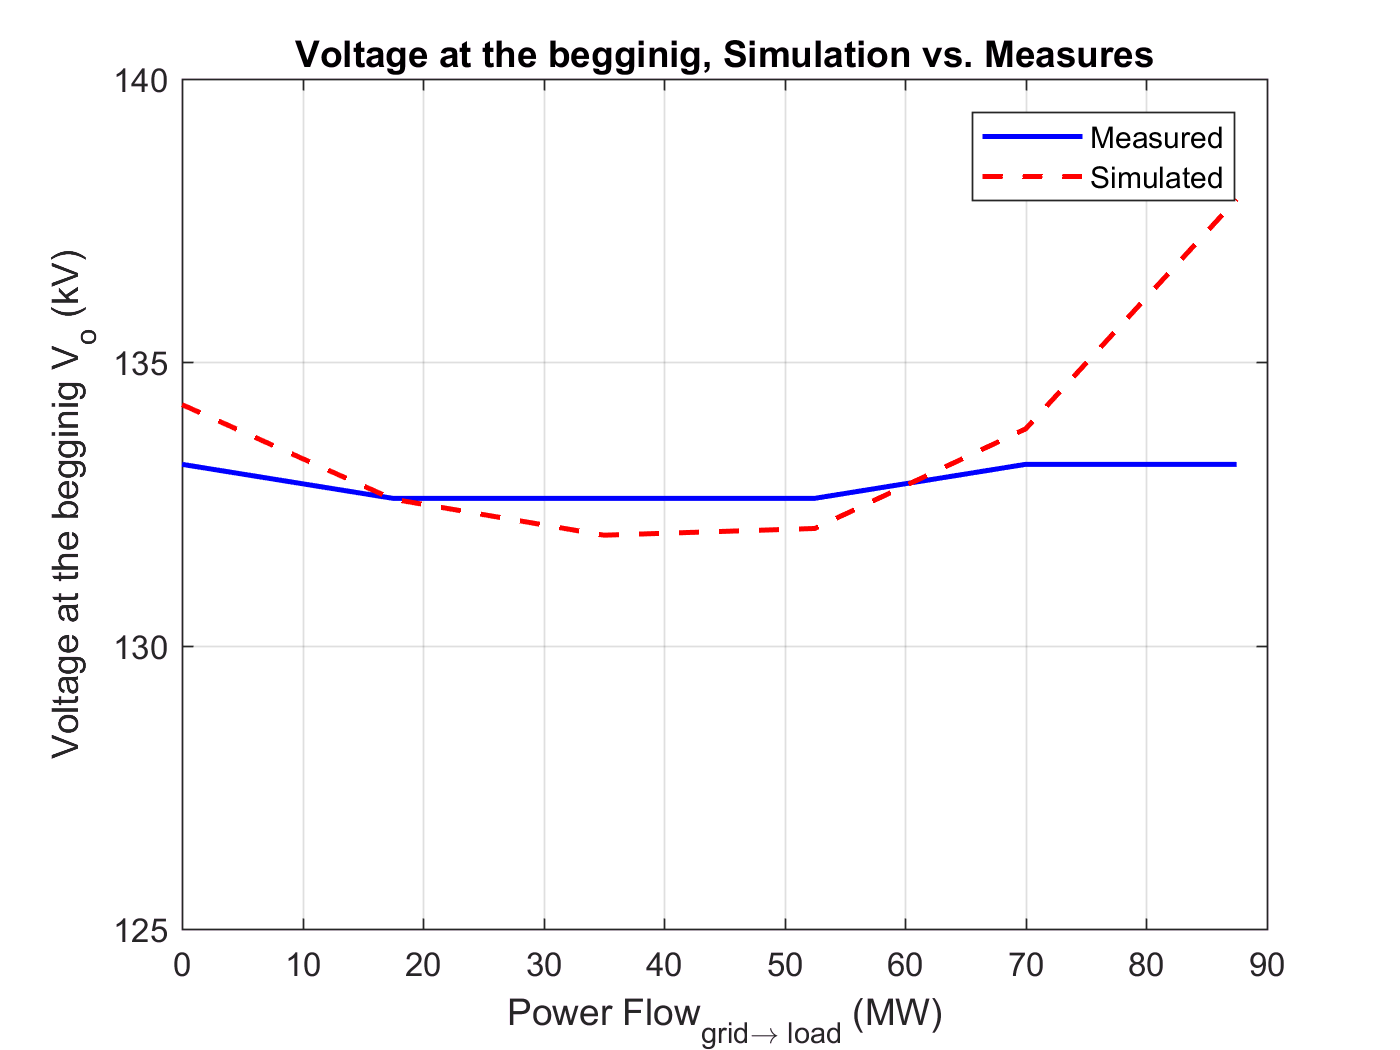

figure(2)
% Tension inicial medida
p1 = plot(Pot*1e-6,sqrt(3)*abs(V_inicial)*1e-3,'b','LineWidth',1.5);
grid on
xlabel('Power Flow_{grid\rightarrow load} (MW)')
ylabel('Voltage at the begginig V_o (kV)')
title('Voltage at the begginig, Simulation vs. Measures')
ylim([125 140])
hold on
% Tensión incial simulación
p2 = plot(Pot*1e-6,sqrt(3)*abs(Vo)*1e-3,'r--','LineWidth',1.5);
legend([p1;p2],'Measured','Simulated');

If we analyze the voltage drop we obtain for every load point:


$$\Delta V^{(i)} = V_o^{(i)}-V_f^{(i)}$$


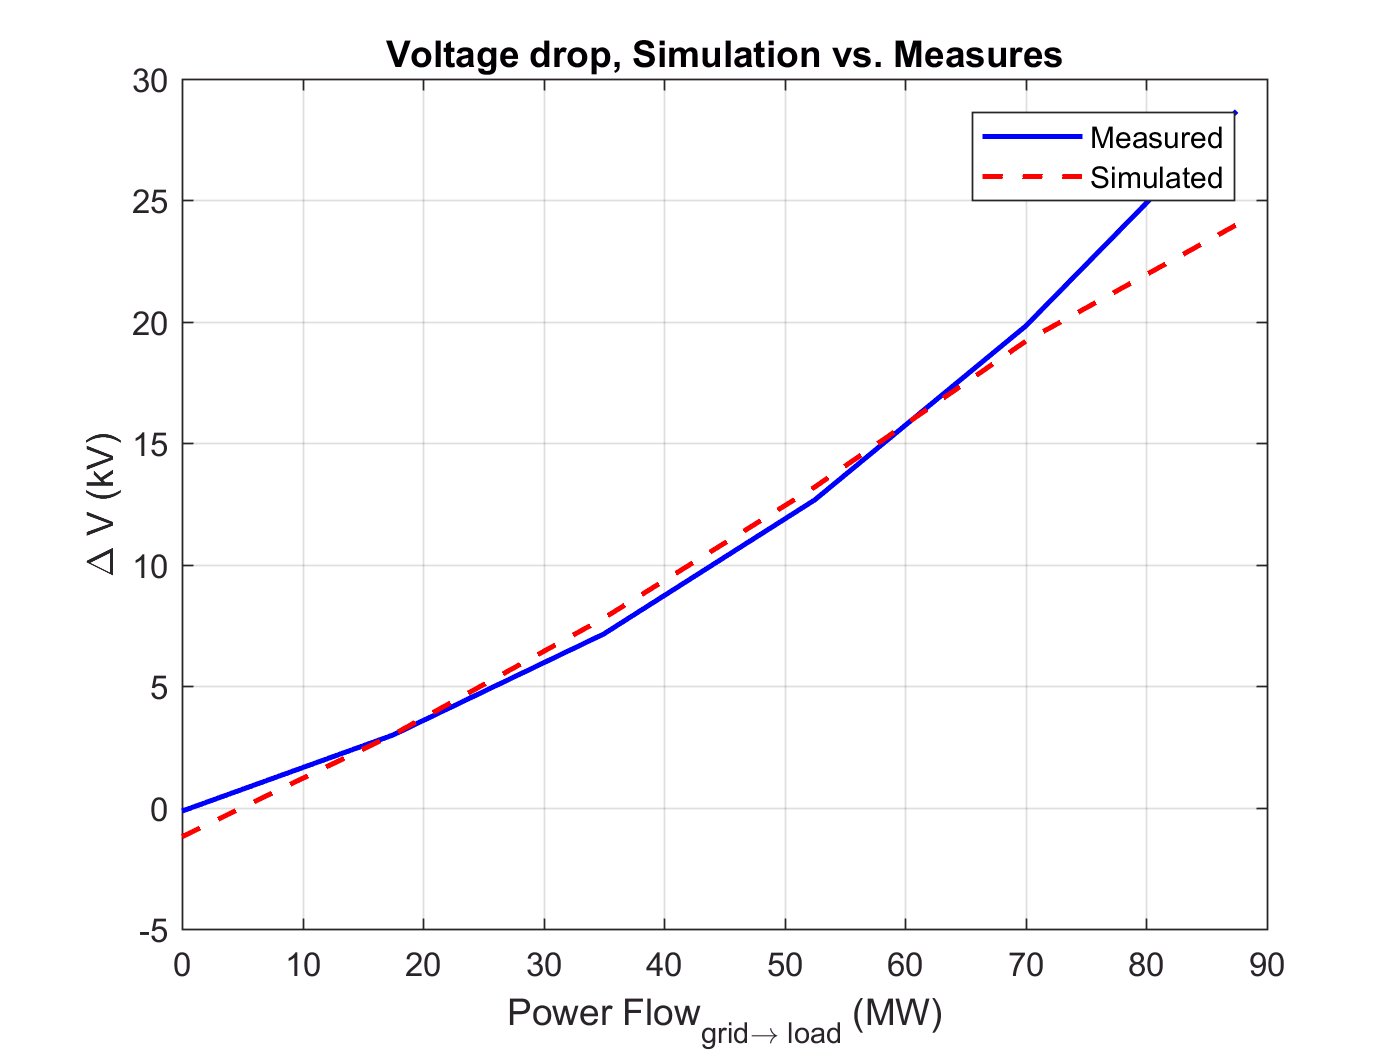

figure(3)
deltav = abs(Vo) - abs(V_final);
deltav_lab = V_inicial - V_final;
p3 = plot(Pot*1e-6,sqrt(3)*deltav*1e-3,'b','LineWidth',1.5);
xlabel('Power Flow_{grid\rightarrow load} (MW)')
ylabel('\Delta V (kV)')
title('Voltage drop, Simulation vs. Measures')
grid on
hold on
p4 = plot(Pot*1e-6,sqrt(3)*deltav_lab*1e-3,'r--','LineWidth',1.5);
legend([p3;p4],'Measured','Simulated')

## Voltage drop simulation: Voltage in the load

**Second hypothesis.** Now, the input data for voltage drop simulation are the current feeding the load $I_{load}$ and the voltage at the beginning $V_{o}$. Then, changing the load (current at the end of the line), we obtain the different values of voltage drop depending on the power flow through the line.


$$I_o =\frac{\left(I_l -C·V_o \right)}{D}$$



$$V_{l\text{ }} =A·V_o +B·I_o$$


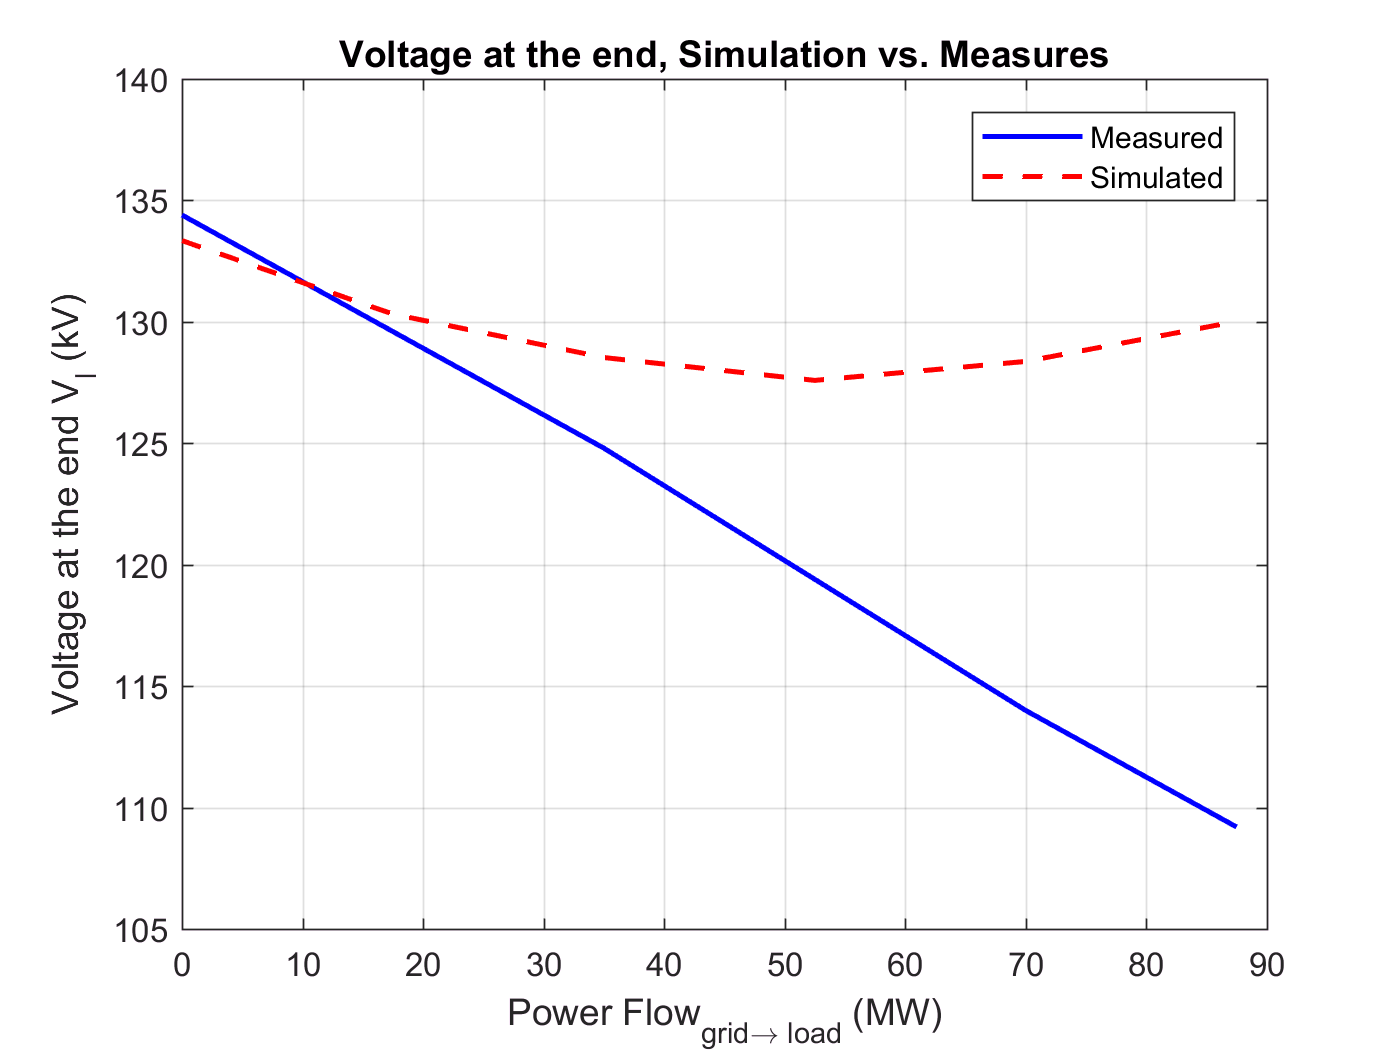

Vl = [];
Io = []; 
for i = 1:length(V_inicial)
    Io(i) = (I_load(i) - C*V_inicial(i))/D;
    Vl(i) = A*V_inicial(i) + B*Io(i);
end

figure(4)
% Tension final medida
p1 = plot(Pot*1e-6,sqrt(3)*abs(V_final)*1e-3,'b','LineWidth',1.5);
grid on
xlabel('Power Flow_{grid\rightarrow load} (MW)')
ylabel('Voltage at the end V_l (kV)')
title('Voltage at the end, Simulation vs. Measures')
ylim([105 140])
hold on
% Tensión incial simulación
p2 = plot(Pot*1e-6,sqrt(3)*abs(Vl)*1e-3,'r--','LineWidth',1.5);
legend([p1;p2],'Measured','Simulated');

If we analyze the voltage drop we obtain for every load point:


$$\Delta V^{(i)} = V_o^{(i)}-V_f^{(i)}$$


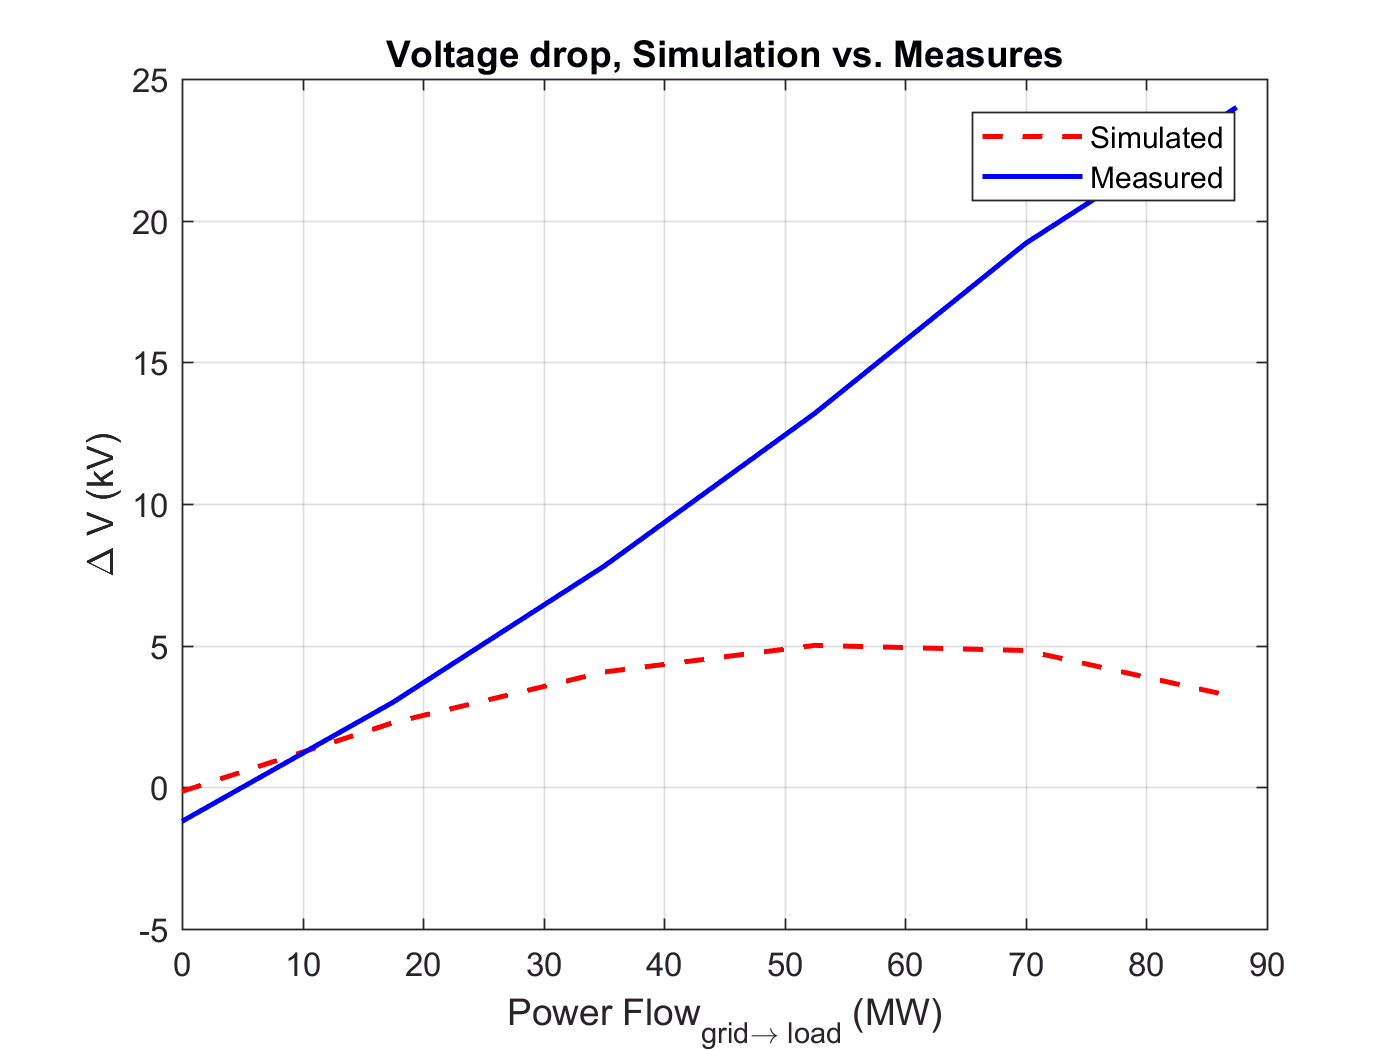

figure(5)
deltav = abs(V_inicial) - abs(Vl);
deltav_lab = V_inicial - V_final;
p3 = plot(Pot*1e-6,sqrt(3)*deltav*1e-3,'r--','LineWidth',1.5);
xlabel('Power Flow_{grid\rightarrow load} (MW)')
ylabel('\Delta V (kV)')
title('Voltage drop, Simulation vs. Measures')
grid on
hold on
p4 = plot(Pot*1e-6,sqrt(3)*deltav_lab*1e-3,'b','LineWidth',1.5);
legend([p3;p4],'Simulated','Measured')

## Analysis of voltage drop in transmission lines with different $R/\chi$ relation.

In this section, some $R/\chi$ medium voltage transmission lines are analyzed, working with different types of loads, $\cos(\varphi)=0.8$ ind, cap, $\cos(\varphi)=1$. 


$$\Delta U = r\cdot I\cdot \cos(\varphi) + \chi\cdot I\cdot \sin(\varphi)$$



$$\Delta U = \frac{1}{U}\cdot\left(r\cdot P + \chi\cdot Q\right)$$


k = 1; 
r_l = [0.5 0.75 1 1.25 1.5 2]*k;
rel =  [ 1 1.25 1.5 1.75 2 2.25];
% Long = [1 2.5 5 10 15 20]
R_tot = r_l;
X_tot = R_tot.*rel;
% Datos de entrada
U_n = 20e3/sqrt(3);
cosphi = 0.5:0.1:1;

S = 4e6/3;
P = S*cosphi;
Q = S*sin(acos(cosphi));
Q(1) = -Q(1); % cos capacitivo

for i = 1:length(R_tot)
    for j = 1:length(P)
        delta_u(i,j) = (1/U_n)*(R_tot(i)*P(j) + X_tot(i)*Q(j));
    end
end
delta_u

delta_u =   -21.1325   80.8290   81.6456   80.8290   77.1276   57.7350
  -50.4487  138.5641  137.9300  134.2339  125.1288   86.6025
  -92.2650  207.8461  204.5222  196.2991  179.4214  115.4701
 -146.5812  288.6751  281.4222  267.0245  240.0056  144.3376
 -213.3975  381.0512  368.6299  346.4102  306.8813  173.2051
 -334.5299  554.2563  532.7376  496.5212  434.3411  230.9401


## Plotting simulation results

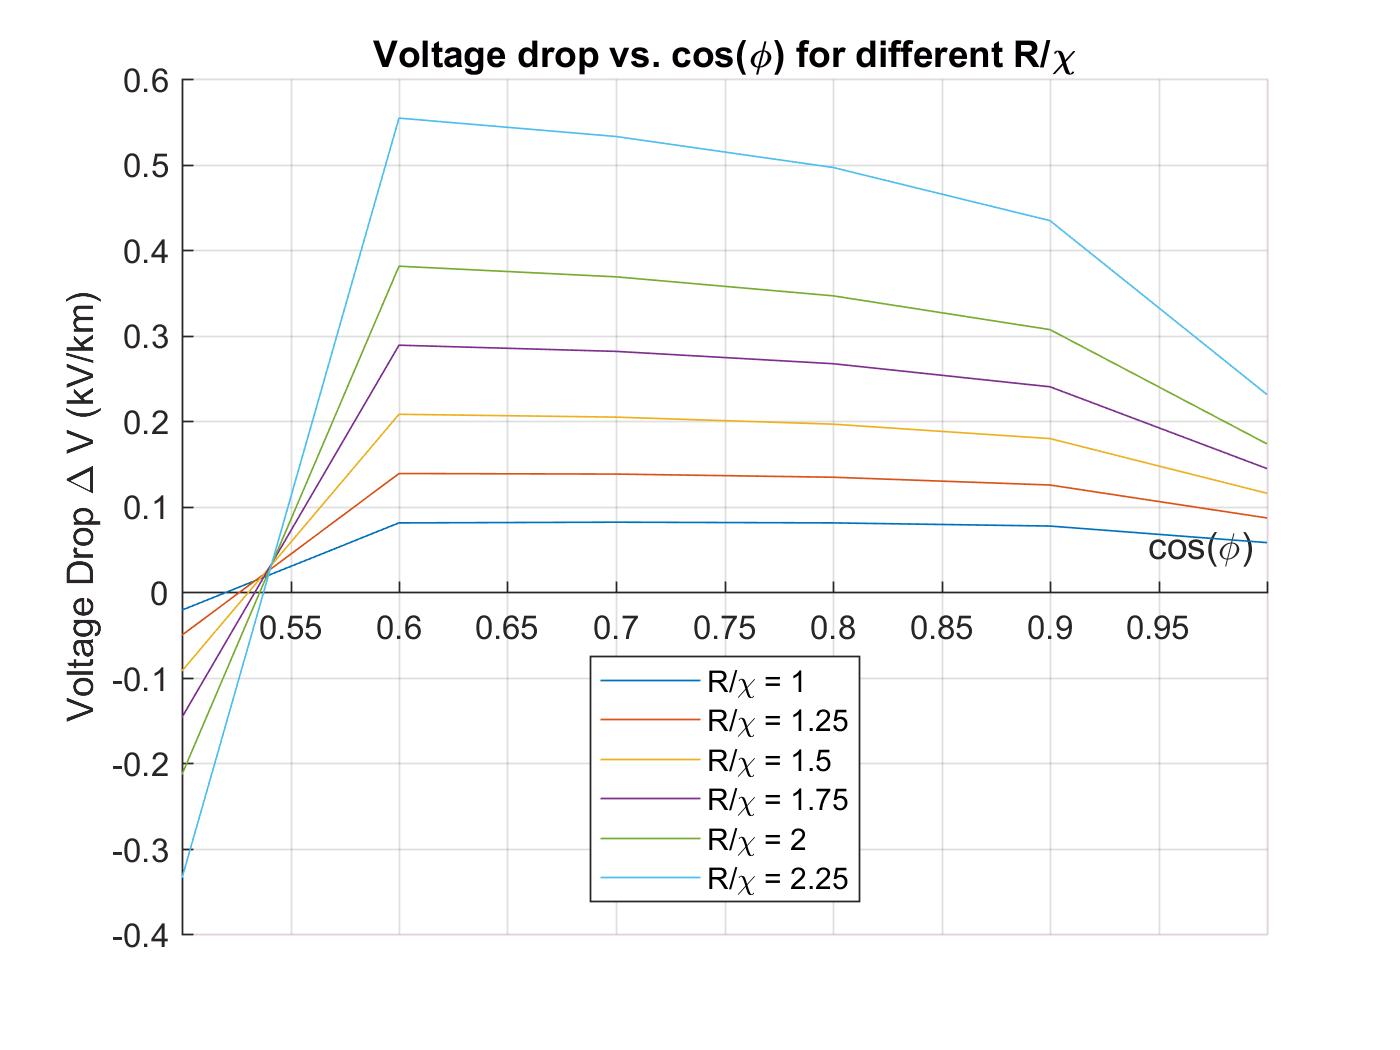

figure 
for i = 1:6
    hold on
    op(i) = plot(cosphi,delta_u(i,:)*1e-3);
    xlabel('cos(\phi)');
    ylabel('Voltage Drop \Delta V (kV/km)')
    grid on
end
ax = gca;
ax.XAxisLocation = 'Origin';
title('Voltage drop vs. cos(\phi) for different R/\chi')
% xlabel('Length (km)')
% ylabel('Voltage Drop \Delta V (V)')
legend( [ op ],'R/\chi = 1','R/\chi = 1.25','R/\chi = 1.5','R/\chi = 1.75','R/\chi = 2','R/\chi = 2.25','Location','South');

## Load working as generator. Voltage drop.

In this section, we assume that the load turn into generator, injecting power in 132 kV voltage level, connected to an infinite grid.


$$V_o =\frac{V_l -B·I_o }{\text{ }A}$$



$$I_l =C·V_o +D·I_{o\text{ }}$$


R_load = r_load*Zbase;
I_load = Ubase./R_load;
Ip = [];
Vo = [];
for i = 1:length(I_load)
    Vo(i) = (Ubase - B*I_load(i))/A;
    Ip(i) = C*Vo(i) + D*I_load(i);
end
volt = Vo;

Plotting results

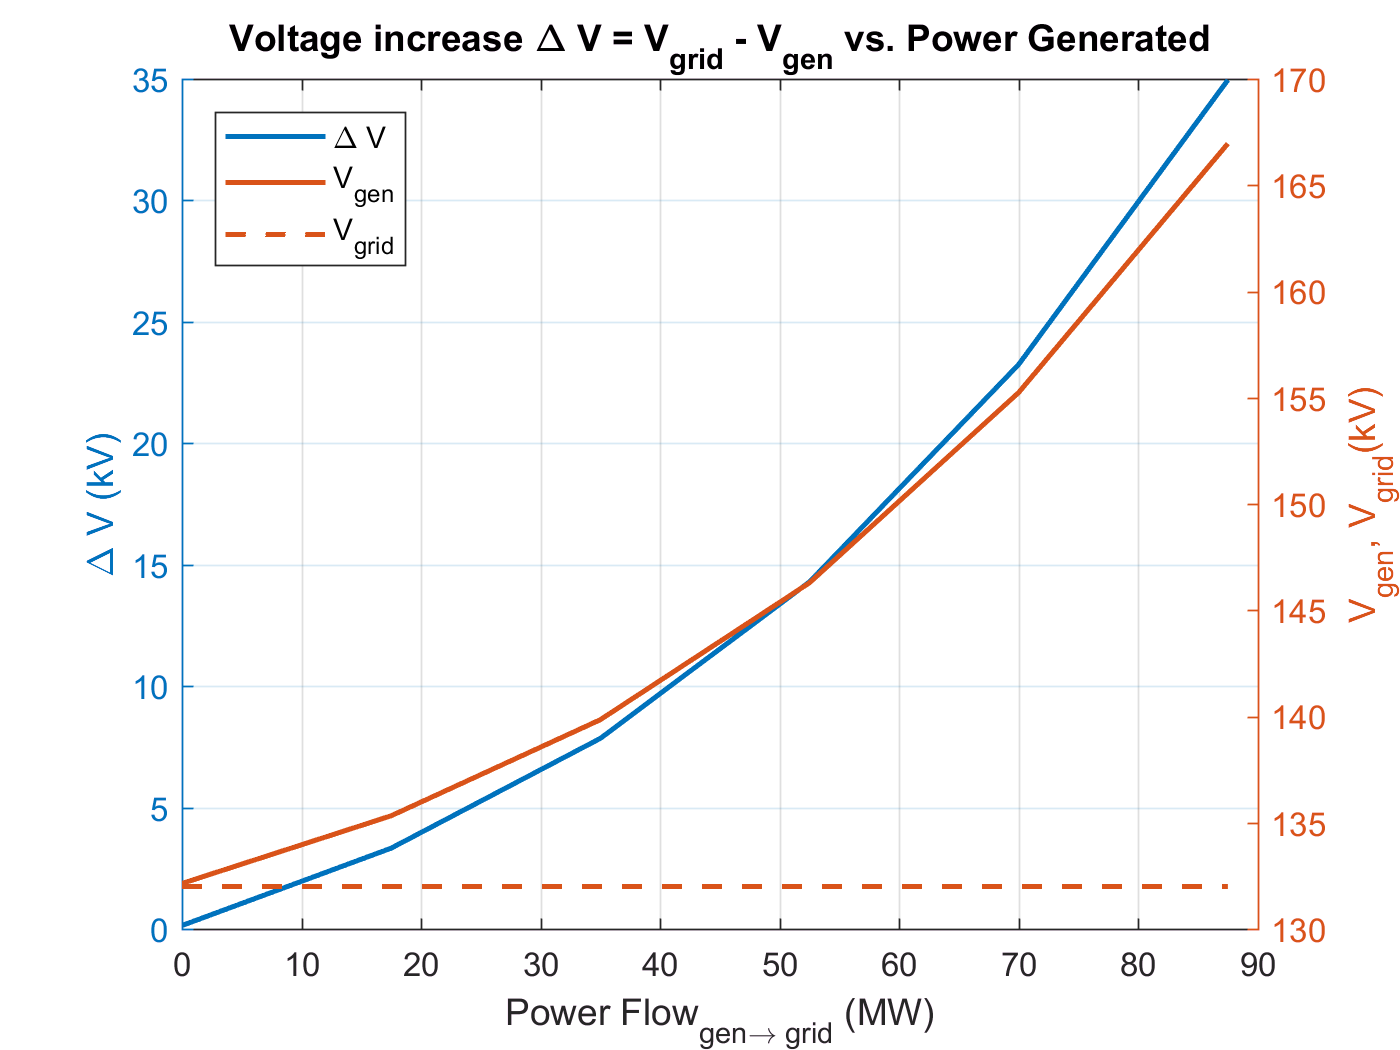

t = [ Ubase Ubase Ubase Ubase Ubase Ubase ];
deltav = -abs(Ubase)+ abs(volt);

% Drop Voltage axis
figure
yyaxis left
p5 = plot(Pot*1e-6,sqrt(3)*deltav*1e-3,'LineWidth',1.5);
xlabel('Power Flow_{gen\rightarrow grid} (MW)')
ylabel('\Delta V (kV)')
title('Voltage drop, Simulation vs. Measures')
grid on
hold on 

% Voltages axis
yyaxis right
p6 = plot(Pot*1e-6,sqrt(3)*abs(volt)*1e-3,'LineWidth',1.5);
xlabel('Power Flow_{gen\rightarrow grid} (MW)')
ylabel('V_{gen}, V_{grid}(kV)')
hold on
p7 = plot(Pot*1e-6,sqrt(3)*Ubase*1e-3 + Pot-Pot,'--','LineWidth',1.5);
title('Voltage increase \Delta V = V_{grid} - V_{gen} vs. Power Generated')
legend( [ p5; p6; p7 ],'\Delta V', 'V_{gen}', 'V_{grid}','Location','NorthWest');

# Conclusions

## **Conclusions from tests and simulations:**

## **According to Distributed Parameters Modell in this case:**

- It behaves properly when it comes to modell voltage and current at the beginning of the line from the ones at the end.

- It does not fit so well when we have mixed input (Voltage at the begginig and current in the load).

- We have found some mistakes that differ a lot from actual lines in the propagation constant $\gamma$, because the speed of propagation is too low in comparison with *c *and what it is common to find in overhead power lines (speed closed to *c*).

- We assume it has to do with Capacitance between lines. A improvement must be done in modelling this electric parameter, whose influence has a determinant role in the rest of the model. (Transfer Matrix, Characteristic Impedance, Reactive Power Losses and Generation).

## **General Solutions:** 

- Compensating with Capacitors, which reduce the voltage drop along the feeder by reducing current flow to loads consuming reactive:

## Power Factor ($\cos(\varphi)$) Compensation.

S_loss = 3*(Vo.*conj(Io) - V_final.*conj(I_load))*1e-6;
Q_loss = imag(S_loss)

Q_loss =    -1.6136    2.3262   16.0892   43.9277   91.4623  163.9248


ang = angle(S_loss(2:6))*180/pi;
j = 1;
w = 1;
for i = 1:length(Q_loss)
    if Q_loss(i) < 0
        Q_L(j) = Q_loss(i);
        j = j + 1;
    else
        Q_C(w) = Q_loss(i);
        w = w + 1;
    end
end 
Q_L = Q_loss(1);
L   = -Ubase^2/(omega*Q_L*1e6);
Q_C = Q_loss(2:6);

Different Capacities obtained to compensate the power factor depending on the power flow injected in the grid are calculated as follows:


$$C = \frac{U^2}{\omega\cdot Q_{line}}\:(F)$$


C = Q_C*1e6./(omega*Ubase^2)*1e6

C =     1.2749    8.8178   24.0748   50.1263   89.8397


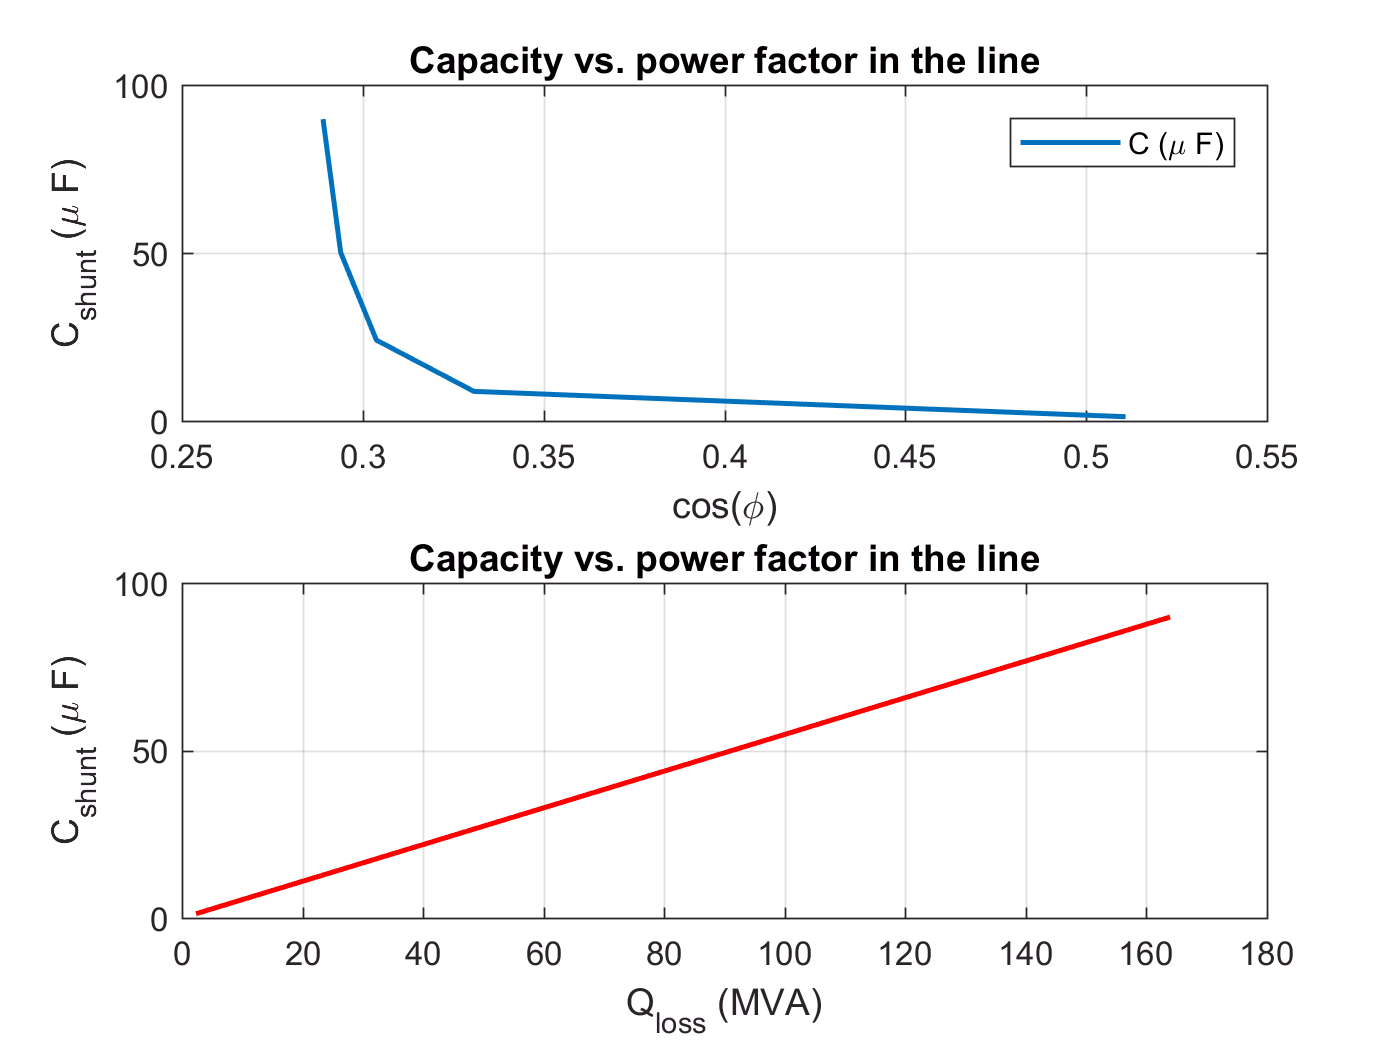

figure
subplot(2,1,1,gca)
plot(cos(ang*pi/180),C,'LineWidth',1.5)
xlabel('cos(\phi)')
ylabel('C_{shunt} (\mu F)')
title('Capacity vs. power factor in the line')
set(gca,'XGrid','on','YGrid','on')
legend('C (\mu F)')

subplot(2,1,2)
plot(Q_loss(2:6),C,'r','LineWidth',1.5)
xlabel('Q_{loss} (MVA)')
ylabel('C_{shunt} (\mu F)')
title('Capacity vs. power factor in the line')
grid on

- FACTS (Series, shunt):

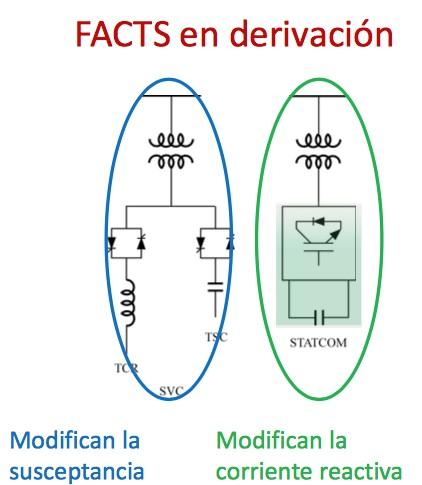

- Shunt FACTs are used to modify the susceptance and the reactive current.

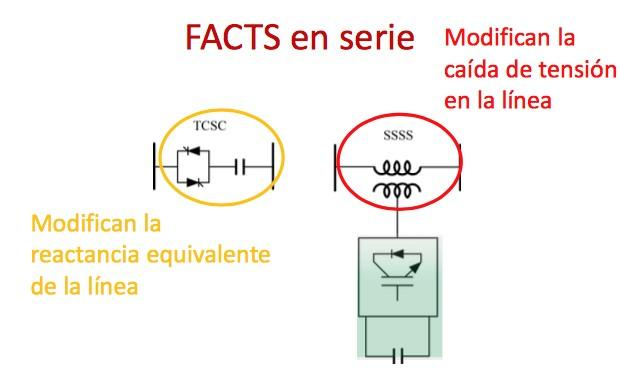

- Series FACTs are used to modify the reactance and therefore the impedance the line has in such a way that voltage can be controlled. 

**Voltage Regulators (Electronic, Electromechanic):**

- Load tap changer (LTC) at the substation transformer, which changes the number of turns ratio in response to load current and thereby adjusts the voltage supplied at the sending end of the feeder or voltage regulators, which are essentially transformers tap changers to adjust the voltage along the feeder, so as to compensate for the voltage drop over distance.